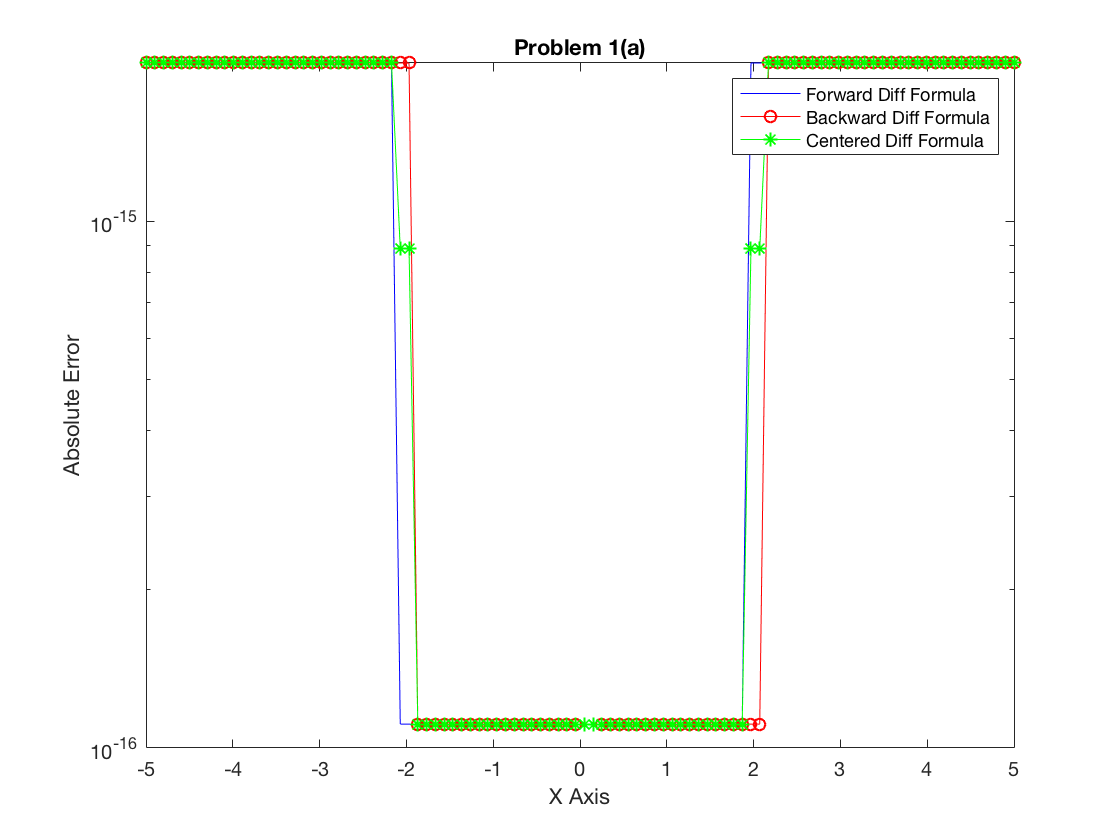

% Nuber 01
x = linspace(-5,5,100);
h = 10/99;

% Approx
f = @(x) x;
f_exact = 1;
f1 = @(x) x.^2;
f1_exact = 2*(x);
f2 = @(x) x.^3; 
f2_exact = 3*x.^2;
f3 = @(x) sin(x);
f3_exact = cos(x);

% Exact
forward = (f(x+h)-f(x))/h;
backward = (f(x)-f(x-h))/h;
centered = (f(x+h)-f(x-h))/(2*h);

forward1 = (f1(x+h)-f1(x))/h;
backward1 = (f1(x)-f1(x-h))/h;
centered1 = (f1(x+h)-f1(x-h))/(2*h);

forward2 = (f2(x+h)-f2(x))/h;
backward2 = (f2(x)-f2(x-h))/h;
centered2 = (f2(x+h)-f2(x-h))/(2*h);

forward3 = (f3(x+h)-f3(x))/h;
backward3 = (f3(x)-f3(x-h))/h;
centered3 = (f3(x+h)-f3(x-h))/(2*h);

%Abs = measured - actual value
% First Function
forwardError = abs(f_exact-forward);
backwardError = abs(f_exact-backward);
centeredError= abs(f_exact-centered);

% % Second Function
forwardError1 = abs(f1_exact-forward1);
backwardError1 = abs(f1_exact-backward1);
centeredError1= abs(f1_exact-centered1);

% % Third Function
forwardError2 = abs(f2_exact-forward2);
backwardError2 = abs(f2_exact-backward2);
centeredError2 = abs(f2_exact-centered2);

% % Fourth Function
forwardError3 = abs(f3_exact-forward3);
backwardError3 = abs(f3_exact-backward3);
centeredError3 = abs(f3_exact-centered3);


% Graph Making
semilogy(x,forwardError,'b-',x, backwardError,'r-o', x, centeredError,'g-*');
title('Problem 1(a)');
legend('Forward Diff Formula','Backward Diff Formula', 'Centered Diff Formula');
xlabel('X Axis');
ylabel('Absolute Error');

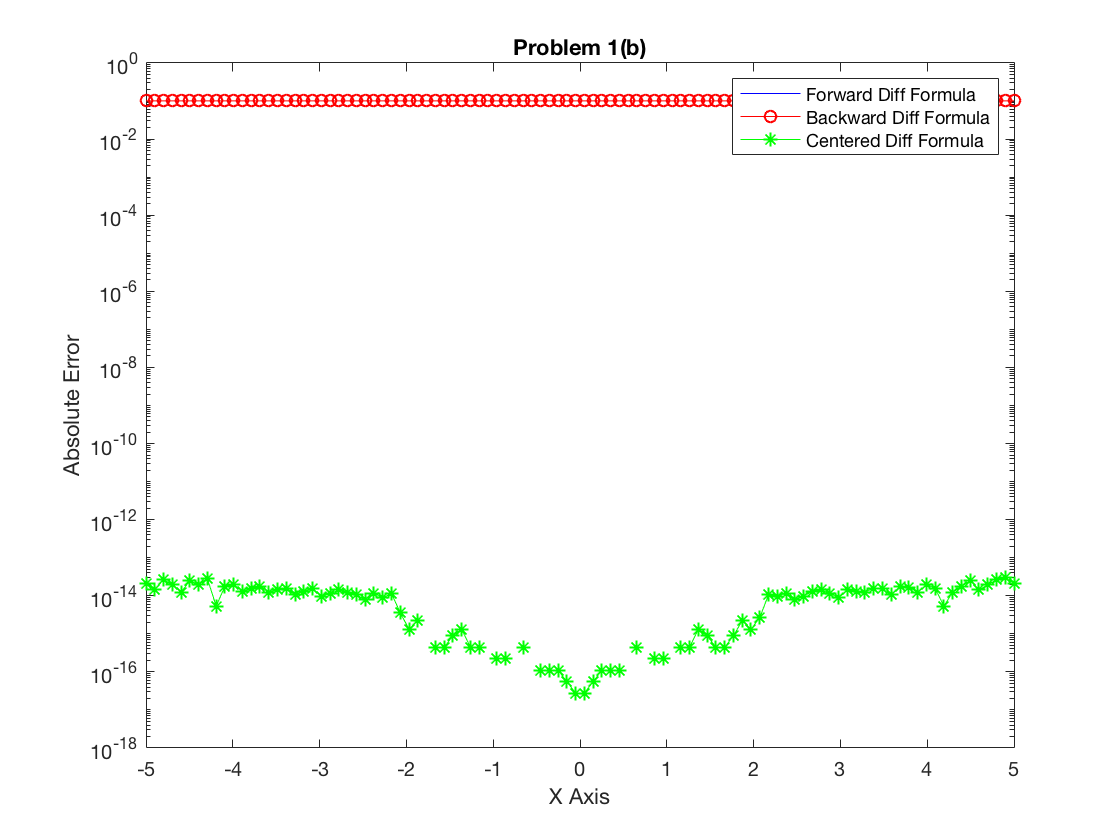

%For graph 1a, most of them are acruate to each other.
semilogy(x,forwardError1,'b-',x, backwardError1,'r-o', x, centeredError1,'g-*');
title('Problem 1(b)');
legend('Forward Diff Formula','Backward Diff Formula', 'Centered Diff Formula');
xlabel('X Axis');
ylabel('Absolute Error');

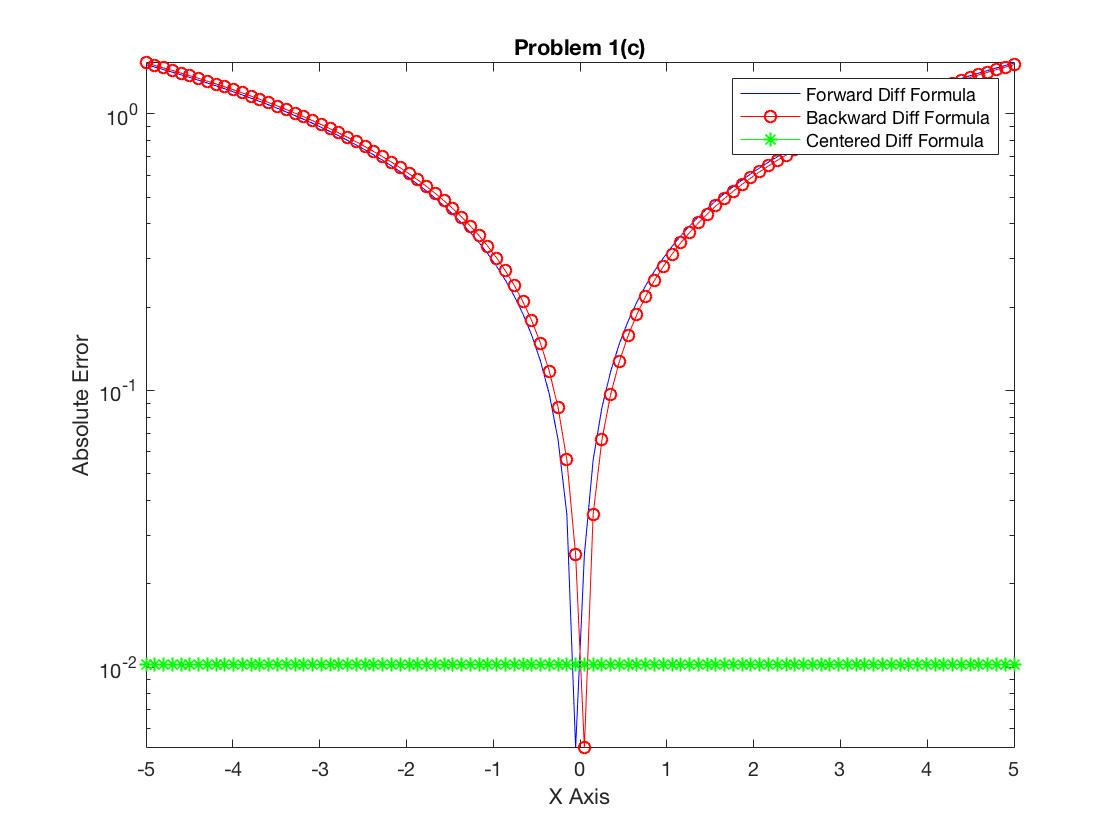

%For graph 1b, Forward and Backward are the same while center flucates accuracy
semilogy(x,forwardError2,'b-',x, backwardError2,'r-o', x, centeredError2,'g-*');
title('Problem 1(c)');
legend('Forward Diff Formula','Backward Diff Formula', 'Centered Diff Formula');
xlabel('X Axis');
ylabel('Absolute Error');

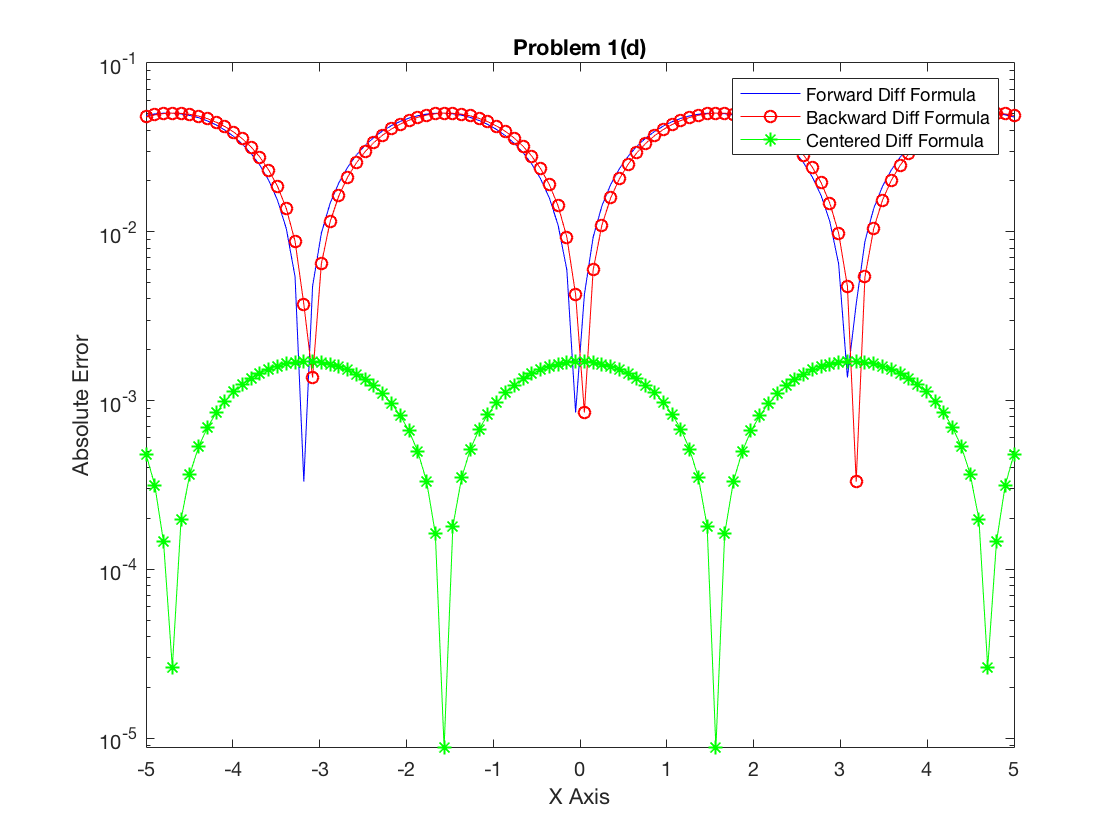

%For graph 1c, Forward and Backward fluctuate accuracy while center is constant
semilogy(x,forwardError3,'b-',x, backwardError3,'r-o', x, centeredError3,'g-*');
title('Problem 1(d)');
legend('Forward Diff Formula','Backward Diff Formula', 'Centered Diff Formula');
xlabel('X Axis');
ylabel('Absolute Error');

% For graph 1d, forward and backward are about the same while centered is shifted
% and is more accurate.

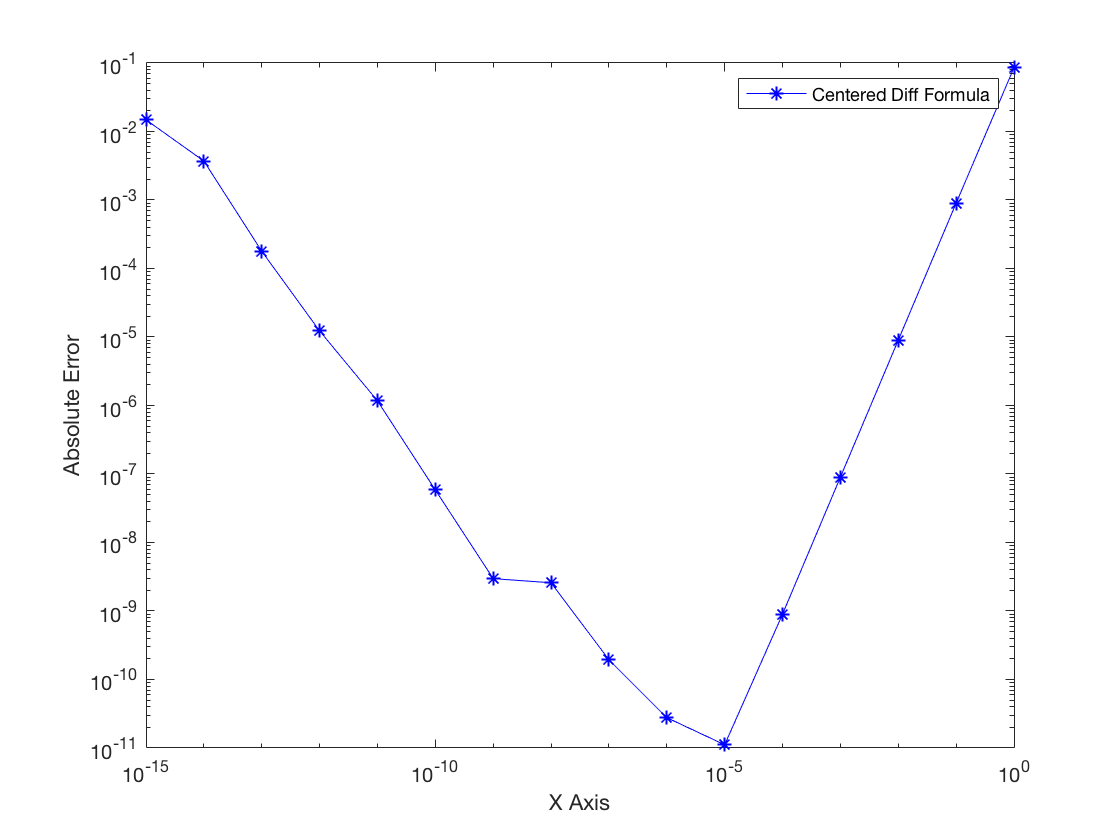

% Number 2
clear
x = 1;

% Approx
f = @(x) sin(x);
f_exact = cos(x);

% Exact
for i = 1:16
    h = 1/10^(i-1);
    X(i) = h;
    centered = (f(x+h)-f(x-h))./(2*h);
    centeredError(i)= abs(f_exact-centered); %Abs = measured - actual value
end

% Graph Making
loglog(X, centeredError,'b-*');
% semilogy(16:-1:1, centeredError,'b-*');
legend('Centered Diff Formula');
xlabel('X Axis');
ylabel('Absolute Error');

% Number 3
% If the number of nodes equals d, then the answer
% should be a constant and if it exceeds d, it does
% not always equal to 0.
f = @(x) 5*x.^3 + 2*x.^2 + 3*x;
X = 1:4;
Y = f(X);
y = num_diff(X,Y,2,3);

function a = linterp_poly(X, Y)
  a = zeros(1,numel(X));
  for i = 1:numel(X)
      aa = poly(X([1:i-1 i+1:end]));
      a = a + Y(i) * aa / polyval(aa, X(i));
  end
end

function y = num_diff(X,Y,x,d)
    p = linterp_poly(X,Y);
    for i = 1:d
        p = polyder(p);
    end
    y = polyval(p,x);
end
